% Cf = 2*pi*f;
% [Kd, Amp, modes]= sh_wave_dispersion(Cf, MATERIAL, B);
% Amp = Amp./Amp(1,:);
% k = Kd/B;

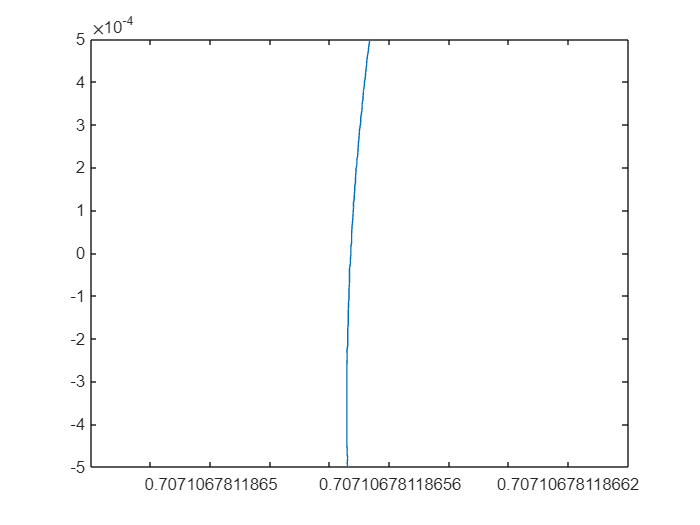

w = Cf;
n = 1;
amp = Amp(:,n);
x1 = 0;
x2 = linspace(-B,B,100);
i_pm = 1;
ik = k(n);

for ii = 1:length(x2)
	u(ii) = SH_u_t(Amp,w,ik,x1,x2(ii),MATERIAL,i_pm);
end

plot(u,x2)